%确定n
clc,clear
n = 3; 
m = 150000;
T1(1,[1:n])=37;
T2(1,[1:n])=37;
T1([1:m],1)=75;
T2([1:m],end)=37;

data = textread('data1.txt');
data(:,4) = data(:,4).*0.001;
midu = sum(data(:,1).*data(:,4))./sum(data(:,4));
c = sum(data(:,1).*data(:,2).*data(:,4))./sum(data(:,1).*data(:,4));
lambda = sum(data(:,4))./sum(data(:,4)./data(:,3));
d = sum(data(:,4));
newdata = [midu*c,lambda,d;402200,0.245,0.0285];
alpha = newdata(:,2)./newdata(:,1);
h = 2000/m;
k = newdata(:,3)./n;
r = alpha.*h./(k.^2);

format long
for i = 1:m
    %T1
    for j = 2:n-1
        T1(i+1,j) = (1-2*r(1)).*T1(i,j)+r(1).*(T1(i,j-1)+T1(i,j+1));
    end
    T1(i+1,n) = T1(i,n) + 2*r(1)*(T1(i,n-1)-T1(i,n))-(2*newdata(2,2)*h/(k(1)*k(2)*newdata(1,1)))*(T2(i,1)-T2(i,2));
    %T2
    T2(i+1,1) = (1-2*r(2)).*T2(i,1)+r(2).*(T1(i,n)+T2(i,2));
    for j = 2:n-1
        T2(i+1,j) = (1-2*r(2)).*T2(i,j)+r(2).*(T2(i,j-1)+T2(i,j+1));
    end
end 

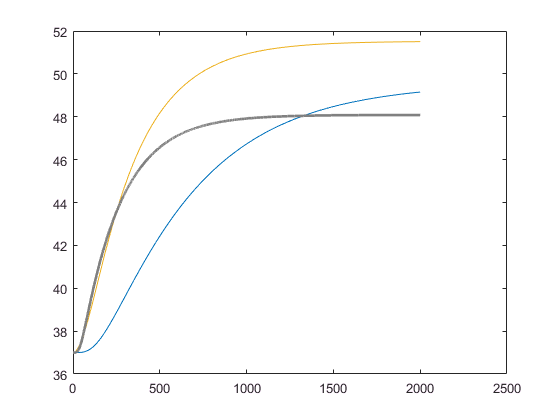

time = h.*[1:m+1];
plot(time,T1(:,n))
hold on
sample = textread('data3.txt');
plot(sample(:,1),sample(:,2),'linewidth',2,'color',[.5 .5 .5])